旋转曲面

生成一条***平面曲线***

% x = [-5:.2:5]
% y = x.^2/4 + 4
% plot(x,y)

生成一条三维曲线

生成一条绕z轴的***三维曲面C***

z1 = [-6:.3:6]

z1 =    -6.0000   -5.7000   -5.4000   -5.1000   -4.8000   -4.5000   -4.2000   -3.9000   -3.6000   -3.3000   -3.0000   -2.7000   -2.4000   -2.1000   -1.8000   -1.5000   -1.2000   -0.9000   -0.6000   -0.3000         0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000    3.6000    3.9000    4.2000    4.5000    4.8000    5.1000    5.4000    5.7000    6.0000


y1 = z1.^2/4 + 4

y1 =    13.0000   12.1225   11.2900   10.5025    9.7600    9.0625    8.4100    7.8025    7.2400    6.7225    6.2500    5.8225    5.4400    5.1025    4.8100    4.5625    4.3600    4.2025    4.0900    4.0225    4.0000    4.0225    4.0900    4.2025    4.3600    4.5625    4.8100    5.1025    5.4400    5.8225    6.2500    6.7225    7.2400    7.8025    8.4100    9.0625    9.7600   10.5025   11.2900   12.1225   13.0000


x1 = z1.^2/4 + 4 - y1

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x1,y1,z1)
hold on
text(0,12,7,'曲线C')


生成一条z轴

y2 = z1 - z1

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = z1 - z1

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x2,y2,z1)
text(0,0,8,'z轴')


生成一条曲线C绕z轴的***旋转曲面***

更具 y = z^2/4  y = sqrt(x^2+y^2） 带入可得 z^2/4 = sqrt(x^2+y^2)

化简得  z = sqrt(4*sqrt(x3.^2+y3.^2)) 或者 z = -sqrt(4*sqrt(x3.^2+y3.^2))

[x3,y3] = meshgrid(-5:.3:5);

surf(x3, y3, real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
surf(x3, y3, -real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
%surf(x3, y3, B)

%hold off

***圆锥面***  由直线 z=ay  y = sqrt(x^2+y^2) 可得 z^2 = a^2(x^2+y^2)

% Oyz平面上的直线
[x4,y4] = meshgrid(-7:1:7);
z4 = y4

z4 =     -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


x4 = z4-y4

x4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x4,y4,z4,'r')
text(0,8,8,'Oxy平面直线')
% 根据 直线生成 圆锥面
[x5,y5] = meshgrid(-5:.3:5);
z5 = sqrt(x5.^2+y5.^2)

z5 =     7.0711    6.8622    6.6603    6.4661    6.2801    6.1033    5.9363    5.7801    5.6356    5.5036    5.3852    5.2811    5.1923    5.1196    5.0636    5.0249    5.0040    5.0010    5.0160    5.0488    5.0990    5.1662    5.2498    5.3488    5.4626    5.5902    5.7306    5.8830    6.0465    6.2201    6.4031    6.5947    6.7941    7.0007
    6.8622    6.6468    6.4382    6.2370    6.0440    5.8600    5.6859    5.5227    5.3712    5.2326    5.1078    4.9980    4.9041    4.8270    4.7676    4.7265    4.7043    4.7011    4.7170    4.7518    4.8052    4.8765    4.9649    5.0695    5.1894    5.3235    5.4708    5.6303    5.8009    5.9816    6.1717    6.3702    6.5765    6.7897
    6.6603    6.4382    6.2225    6.0141    5.8138    5.6223    5.4406    5.2697    5.1108    4.9649    4.8332    4.7170    4.6174    4.5354    4.4721    4.4283    4.4045    4.4011    4.4181    4.4553    4.5122    4.5880    4.6819    4.7927    4.9193    5.0606    5.2154    5.3824    5.5606    5.7489    5.9464   

%mesh(x5,y5,real(z5))
mesh(x5,y5,-real(z5))


旋转抛物面 由抛物线 z = ay^2 可得   z = a(x^2+y^2)

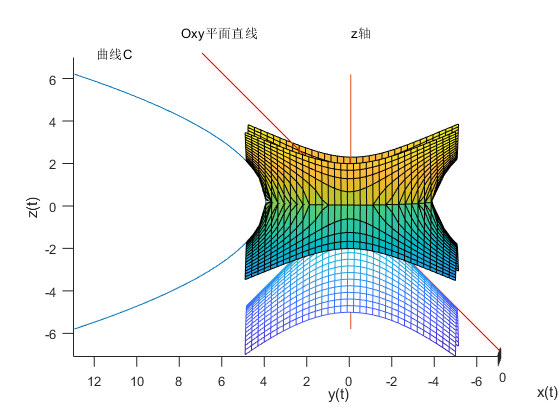

[x5,y5] = meshgrid(-5:.3:5);


xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
axis equal 